% analytic_strain_modeling.m

syms tr tm x y
rotmat_m1 = [cos(tm/2), -sin(tm/2); sin(tm/2), cos(tm/2)];
rotmat_m2 = [cos(tm/2), sin(tm/2); -sin(tm/2), cos(tm/2)];
trxy = exp(-x^2-y^2)*tr;
rotmat_r1 = [cos(trxy/2), -sin(trxy/2); sin(trxy/2), cos(trxy/2)];
rotmat_r2 = [cos(trxy/2), sin(trxy/2); -sin(trxy/2), cos(trxy/2)];

a1_0 = [x;y];
a2_0 = [x;y];

a1_m = rotmat_m1*a1_0;
a2_m = rotmat_m2*a2_0;
a1_r = rotmat_r1*a1_m;
a2_r = rotmat_r2*a2_m;

u_m = a1_m - a2_m;
disp('u_m(x,y)');

u_m(x,y)



exx_m = diff(u_m(1),'x');
exy_m = diff(u_m(1),'y');
eyx_m = diff(u_m(2),'x');
eyy_m = diff(u_m(2),'y');

u_r = a1_r - a2_r;
disp('u_r(x,y)');

u_r(x,y)


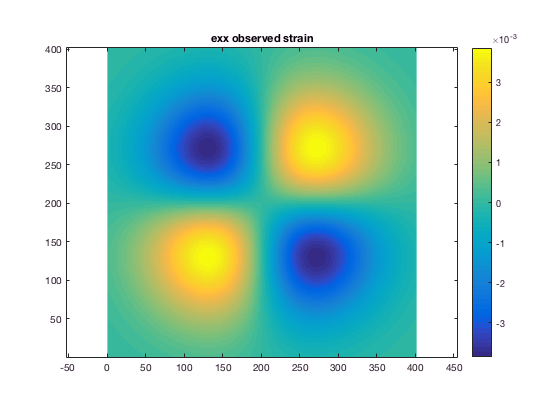


exx_obs_r = simplify(diff(u_r(1),'x'));
exy_obs_r = simplify(diff(u_r(1),'y'));
eyx_obs_r = simplify(diff(u_r(2),'x'));
eyy_obs_r = simplify(diff(u_r(2),'y'));

xbase = -2:0.01:2;
ybase = -2:0.01:2;
[xspace,yspace] = meshgrid(xbase,ybase);
exx_obs_fun = matlabFunction(exx_obs_r);
exy_obs_fun = matlabFunction(exy_obs_r);
eyx_obs_fun = matlabFunction(eyx_obs_r);
eyy_obs_fun = matlabFunction(eyy_obs_r);

theta_m = deg2rad(1.2);
theta_r = deg2rad(0.6);
figure;
imagesc(exx_obs_fun(theta_m,theta_r,xspace,yspace)); title('exx observed strain'); axis equal; set(gca,'yDir','normal'); colorbar;

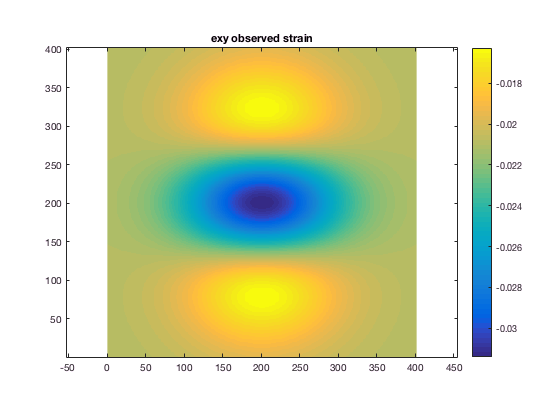

figure;
imagesc(exy_obs_fun(theta_m,theta_r,xspace,yspace)); title('exy observed strain'); axis equal; set(gca,'yDir','normal'); colorbar;

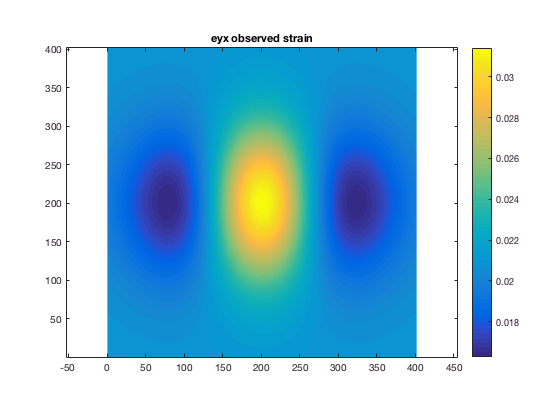

figure;
imagesc(eyx_obs_fun(theta_m,theta_r,xspace,yspace)); title('eyx observed strain'); axis equal; set(gca,'yDir','normal'); colorbar;

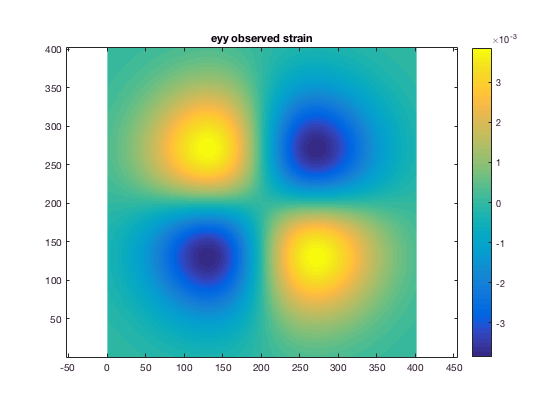

figure;
imagesc(eyy_obs_fun(theta_m,theta_r,xspace,yspace)); title('eyy observed strain'); axis equal; set(gca,'yDir','normal'); colorbar;

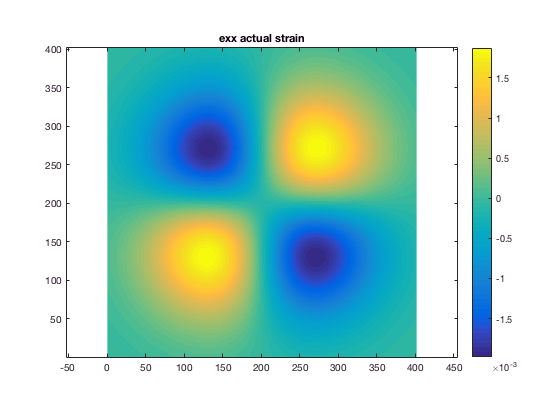


exx_actual_1r = simplify(diff(a1_r(1),'x') - 1);  % would expect x and y components to vary linearly with themselves and themselves only. 
exy_actual_1r = simplify(diff(a1_r(1),'y'));
eyx_actual_1r = simplify(diff(a1_r(2),'x'));
eyy_actual_1r = simplify(diff(a1_r(2),'y') - 1);
exx_actual_fun = matlabFunction(exx_actual_1r);
exy_actual_fun = matlabFunction(exy_actual_1r);
eyx_actual_fun = matlabFunction(eyx_actual_1r);
eyy_actual_fun = matlabFunction(eyy_actual_1r);

figure;
imagesc(exx_actual_fun(theta_m,theta_r,xspace,yspace)); title('exx actual strain'); axis equal; set(gca,'yDir','normal'); colorbar;

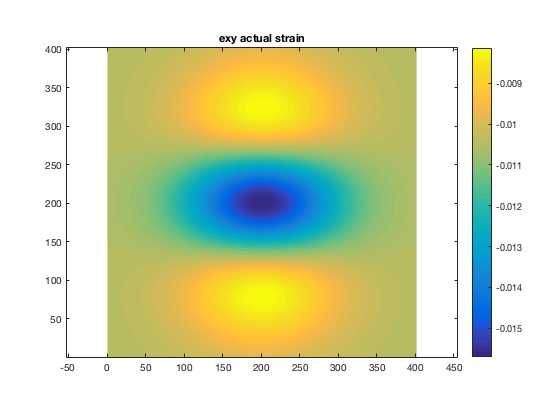

figure;
imagesc(exy_actual_fun(theta_m,theta_r,xspace,yspace)); title('exy actual strain'); axis equal; set(gca,'yDir','normal'); colorbar;

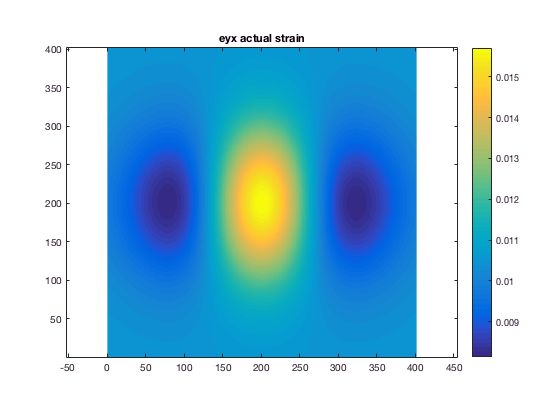

figure;
imagesc(eyx_actual_fun(theta_m,theta_r,xspace,yspace)); title('eyx actual strain'); axis equal; set(gca,'yDir','normal'); colorbar;

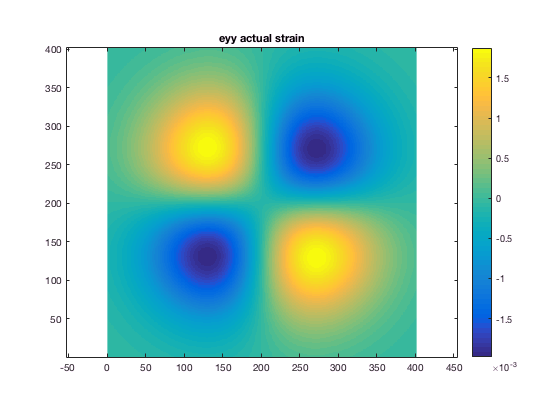

figure;
imagesc(eyy_actual_fun(theta_m,theta_r,xspace,yspace)); title('eyy actual strain'); axis equal; set(gca,'yDir','normal'); colorbar;

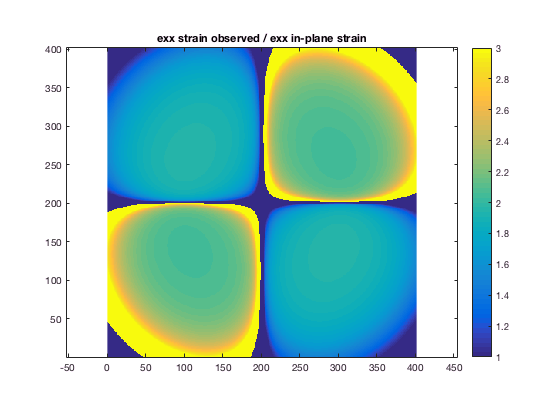


% Would appear that the simplification of the analytic expression is beyond
% the simplification routine here. Try it numerically.
exx_ratio_ana = simplify(exx_obs_r/exx_actual_1r);
exy_ratio_ana = simplify(exy_obs_r/exy_actual_1r);
eyx_ratio_ana = simplify(eyx_obs_r/eyx_actual_1r);
eyy_ratio_ana = simplify(eyy_obs_r/eyy_actual_1r);

% No, it actually appears that the ratio is not exact, though close,
% especially at large strain induced by the twist.
exx_ratio = exx_obs_fun(theta_m,theta_r,xspace,yspace)./exx_actual_fun(theta_m,theta_r,xspace,yspace);
exx_ratiofun = matlabFunction(exx_ratio_ana);
figure; imagesc(exx_ratiofun(theta_m,theta_r,xspace,yspace)); caxis([1,3]); title('exx strain observed / exx in-plane strain'); axis equal; set(gca,'yDir','normal'); colorbar;

% If however the moire angle is ignored, then the observed strain appears
% to be a multiple of 2 of the actual interlayer strain. Note the reason
% this is interesting for exx is that it has no strain from the raw Moire,
% but the reconstruction process induces strain. 
figure; imagesc(exx_ratiofun(theta_m,theta_r,xspace,yspace)); caxis([1,3]); title('exx strain observed / exx in-plane strain'); axis equal; set(gca,'yDir','normal'); colorbar;

% Can we show this analytically?
exx_obs_nom = subs(exx_obs_r,tm,0);
exx_actual_nom = subs(exx_actual_1r,tm,0);
exx_nom_ratio = simplify(exx_obs_nom/exx_actual_nom);
exx_ratio_ana

$$exx\_ratio\_ana = \begin{array}{l} \frac{2\,\mathrm{tr}\,x\,y\,\sigma_{1}}{{\mathrm{e}}^{x^{2}+y^{2}}\,\sigma_{1}-{\mathrm{e}}^{x^{2}+y^{2}}+\mathrm{tr}\,x^{2}\,\sin\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x\,y\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}$$

exx_nom_ratio

$$exx\_nom\_ratio = \begin{array}{l} \frac{2\,\mathrm{tr}\,x\,y\,\sigma_{1}}{{\mathrm{e}}^{x^{2}+y^{2}}\,\sigma_{1}-{\mathrm{e}}^{x^{2}+y^{2}}+\mathrm{tr}\,x^{2}\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x\,y\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}$$

exx_obs_r

$$exx\_obs\_r = 2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\cos\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)$$

exx_actual_1r

$$exx\_actual\_1r = \begin{array}{l} \cos\left(\sigma_{1}\right)+\mathrm{tr}\,x^{2}\,\sigma_{2}\,\sin\left(\sigma_{1}\right)+\mathrm{tr}\,x\,y\,\sigma_{2}\,\cos\left(\sigma_{1}\right)-1\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,\sigma_{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

## New section


u_r

$$u\_r = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\,\sigma_{4}-\sigma_{1}\,\sigma_{6}-\sigma_{2}\,\sigma_{5}-\sigma_{2}\,\sigma_{3}\\ \sigma_{1}\,\sigma_{5}-\sigma_{1}\,\sigma_{3}+\sigma_{2}\,\sigma_{6}+\sigma_{2}\,\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ \sigma_{2}=\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ \sigma_{3}=y\,\cos\left(\frac{\mathrm{tm}}{2}\right)-x\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ \sigma_{4}=x\,\cos\left(\frac{\mathrm{tm}}{2}\right)-y\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ \sigma_{5}=y\,\cos\left(\frac{\mathrm{tm}}{2}\right)+x\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ \sigma_{6}=x\,\cos\left(\frac{\mathrm{tm}}{2}\right)+y\,\sin\left(\frac{\mathrm{tm}}{2}\right) \end{array}$$

simplify(u_r)

$$ans = \left(\begin{array}{c} -2\,y\,\sin\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ 2\,x\,\sin\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}\right)$$

u_m

$$u\_m = \left(\begin{array}{c} -2\,y\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ 2\,x\,\sin\left(\frac{\mathrm{tm}}{2}\right) \end{array}\right)$$

exx_obs_r

$$exx\_obs\_r = 2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\cos\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)$$

a1_r

$$a1\_r = \begin{array}{l} \left(\begin{array}{c} \sigma_{3}\,\sigma_{1}-\sigma_{4}\,\sigma_{2}\\ \sigma_{3}\,\sigma_{2}+\sigma_{4}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x\,\cos\left(\frac{\mathrm{tm}}{2}\right)-y\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ \sigma_{2}=y\,\cos\left(\frac{\mathrm{tm}}{2}\right)+x\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ \sigma_{3}=\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ \sigma_{4}=\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}$$

a1_m

$$a1\_m = \left(\begin{array}{c} x\,\cos\left(\frac{\mathrm{tm}}{2}\right)-y\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ y\,\cos\left(\frac{\mathrm{tm}}{2}\right)+x\,\sin\left(\frac{\mathrm{tm}}{2}\right) \end{array}\right)$$

exx_actual_1r = simplify(diff(a1_r(1),'x') - 1)

$$exx\_actual\_1r = \begin{array}{l} \cos\left(\sigma_{1}\right)+\mathrm{tr}\,x^{2}\,\sigma_{2}\,\sin\left(\sigma_{1}\right)+\mathrm{tr}\,x\,y\,\sigma_{2}\,\cos\left(\sigma_{1}\right)-1\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,\sigma_{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

exx_actual_1m = simplify(diff(a1_m(1),'x') - 1)  % would expect x and y components to vary linearly with themselves and themselves only. 

$$exx\_actual\_1m = \cos\left(\frac{\mathrm{tm}}{2}\right)-1$$

% exy_actual_1r = simplify(diff(a1_r(1),'y'));
% eyx_actual_1r = simplify(diff(a1_r(2),'x'));
% eyy_actual_1r = simplify(diff(a1_r(2),'y') - 1);


## Intralayer strain calculation try 2

% The right way to do this is to calculate uintra, which is not a displacement between the two layers, but rather a displacement between the  
% unstrained latticed positions (which we will take here as the unreconstructed moire) and the strained lattice positions.
% Differentiate that displacement to get strain, I believe. It's not meaningful to differentiate the atomic coordinates.
uintra_r = simplify(a1_r - a1_m);
exx_uintrar = simplify(diff(uintra_r(1),x));
exy_uintrar = simplify(diff(uintra_r(1),y));
eyx_uintrar = simplify(diff(uintra_r(2),x));
eyy_uintrar = simplify(diff(uintra_r(2),y));
uintra_r

$$uintra\_r = \begin{array}{l} \left(\begin{array}{c} y\,\sin\left(\frac{\mathrm{tm}}{2}\right)-x\,\cos\left(\frac{\mathrm{tm}}{2}\right)+\sigma_{3}\,\sigma_{1}-\sigma_{4}\,\sigma_{2}\\ \sigma_{3}\,\sigma_{2}-x\,\sin\left(\frac{\mathrm{tm}}{2}\right)-y\,\cos\left(\frac{\mathrm{tm}}{2}\right)+\sigma_{4}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x\,\cos\left(\frac{\mathrm{tm}}{2}\right)-y\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ \sigma_{2}=y\,\cos\left(\frac{\mathrm{tm}}{2}\right)+x\,\sin\left(\frac{\mathrm{tm}}{2}\right)\\ \sigma_{3}=\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)\\ \sigma_{4}=\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}$$

% Why is this not working?? There is no way the intralayer xx strain should depend on tm.
% Oh, I guess it may be because there it orients the axes a bit differently, so when you differentiate with respect to 'x' the coordinate system has changed.
% I suspect we could demonstrate that term is very small. Perhaps that is the case in the above plots.
exx_uintrar

$$exx\_uintrar = \begin{array}{l} \cos\left(\sigma_{1}\right)-\cos\left(\frac{\mathrm{tm}}{2}\right)+\mathrm{tr}\,x^{2}\,\sigma_{2}\,\sin\left(\sigma_{1}\right)+\mathrm{tr}\,x\,y\,\sigma_{2}\,\cos\left(\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,\sigma_{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

eyy_uintrar

$$eyy\_uintrar = \begin{array}{l} \cos\left(\sigma_{1}\right)-\cos\left(\frac{\mathrm{tm}}{2}\right)+\mathrm{tr}\,y^{2}\,\sigma_{2}\,\sin\left(\sigma_{1}\right)-\mathrm{tr}\,x\,y\,\sigma_{2}\,\cos\left(\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,\sigma_{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

exx_uintrar - eyy_uintrar  % So no, even this doesn't work because that stupid tm term gets into every trig expression there is. 

$$ans = \begin{array}{l} \mathrm{tr}\,x^{2}\,\sigma_{1}\,\sin\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,\sigma_{1}}{2}\right)-\mathrm{tr}\,y^{2}\,\sigma_{1}\,\sin\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,\sigma_{1}}{2}\right)+2\,\mathrm{tr}\,x\,y\,\sigma_{1}\,\cos\left(\frac{\mathrm{tm}}{2}+\frac{\mathrm{tr}\,\sigma_{1}}{2}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

% To make the case easier: perform the rotation on a centered layer, equivalent to substituting tm = 0;

exx_uintrar_m0 = subs(exx_uintrar,tm,0)   % sanity check: if tr goes to zero as well this still goes to zero.

$$exx\_uintrar\_m0 = \cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)-1$$

% Now let's verify that under such an approximation, this quantity is exactly half of the interlayer displacement:
a1_r_m0 = subs(a1_r,tm,0);
a2_r_m0 = subs(a2_r,tm,0);
u_observed_m0 = a1_r_m0 - a2_r_m0;
exx_observed_m0 = diff(u_observed_m0(1),x)

$$exx\_observed\_m0 = 2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)$$

simplify(exx_observed_m0/exx_uintrar_m0)

$$ans = \begin{array}{l} \frac{2\,\mathrm{tr}\,x\,y\,\sigma_{1}}{{\mathrm{e}}^{x^{2}+y^{2}}\,\sigma_{1}-{\mathrm{e}}^{x^{2}+y^{2}}+\mathrm{tr}\,x^{2}\,\sin\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right)+\mathrm{tr}\,x\,y\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}\right) \end{array}$$

% Conceptually why must this be??
